GLR_st.name='GLR';
GLR_st.lat=48.51028;
GLR_st.lon=-113.997;
GLR_st.alt=939;
GLR_st.env='con';
GLR_st.footp='F';


GLR_rd=read_betsy('GLR_head',GLR_st.name);

datevec(GLR_rd.Time(1))

ans =         2007          10           2           0           0           0

datevec(GLR_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(GLR_rd.U_S,[5 50 95])

ans =    48.4840   77.5350   95.0115

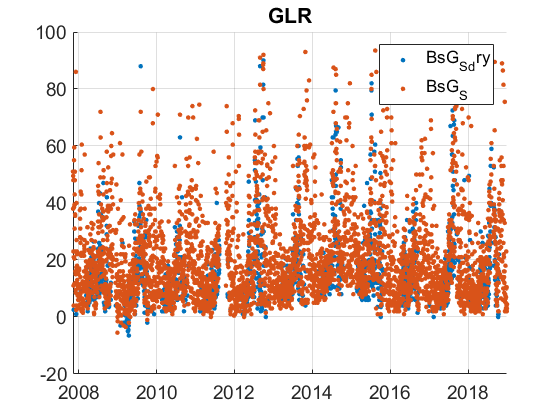

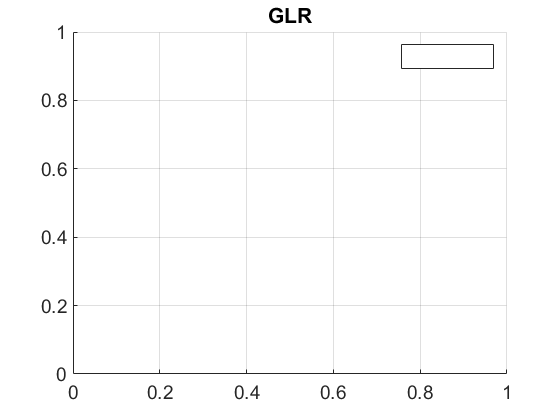

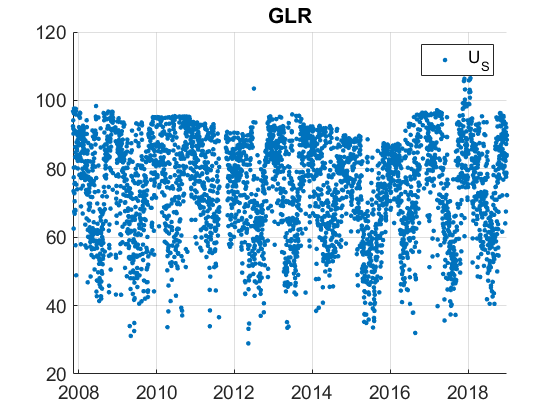

plotFigControl(GLR_rd,GLR_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% GLR_cal=compute_exp_SSA(GLR_rd,lambdaSC, lambdaAE);
% plotFigControl_cal(GLR_cal,GLR_st.name);

%Questions:
%problems:
%sca: sca minima increases from 2012 to August 2015 and abruptly decreases thereafter: was there an intrumental change/reparation?

GLR_tr=GLR_rd;
GLR_tr.y=year(GLR_tr.Time);
% begin at the beginning of a year: 2008
%end  2018
P=timerange('2008-01-01','2019-01-01');
GLR_tr=GLR_tr(P,:);

names=fieldnames(GLR_tr);
c=startsWith(names,'T_') | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    GLR_tr.(N{i})=[];
end

%higher minima from
%dry: a lot missing in winter since 2013 until May 2015 (instrument change)
%to delete ?
% %removing the strange period change the trend from ss to not ss, both positive anyhow.
%better to remove!!
period=timerange('2013-01-01','2015-05-31');

GLR_tr.BsG_S(period)=NaN;
GLR_tr.BsG_S_dry(period)=NaN;

GLR_result=all_trend_STN(GLR_tr,GLR_st);

GLR_result_D=GLR_result;
